# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 박현수    **

**학번**** : 201716193 **

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/hyeonsu3/HW2**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

%DFT
x=[1,2,2,1]; N=4;
X=dft(x,N)

X =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i


%IDFT
y=idft(X,N)

y =    1.0000 - 0.0000i   2.0000 - 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


%DTFT
n= 0:3; k=0:3; w=(pi/4)*k;
X2=x*(exp(-j*pi/4)).^(n'*k)

X2 =    6.0000 + 0.0000i   1.7071 - 4.1213i  -1.0000 - 1.0000i   0.2929 - 0.1213i


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x=[1,2,2,1,zeros(1,12)]; N=16;X=dft(x,N)

X =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i


y=idft(X,N)

y =    1.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 - 0.0000i   1.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xn=[4,1,-1,1]; N=4;
Xk=dfs(xn,N)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

xn=[1,0,-1,-1,0]; N=5;
Xk=dfs(xn,N)

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n=[0:1:100]; x=(sinc((n-50)/2)).^2;
y=x(1:1:100);
Y=dft(y,100); magY=abs(Y); angY=angle(Y);
n1=0:1:99;
figure()
subplot(2,2,1)
stem(n1,magY)
title('magY')
subplot(2,2,2)
stem(n1,angY)
title('angY')

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

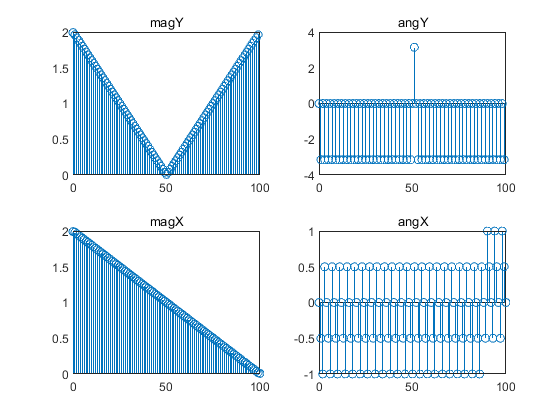

%n=[0:1:100]; x=sinc((n-50)/2).^2;
k=0:100;
w=(pi/100)*k; 
X=x*(exp(-j*pi/100)).^(n'*k);
magX=abs(X); angX=angle(X);
subplot(2,2,3)
stem(k,magX);
title('magX');
subplot(2,2,4)
stem(k,angX/pi);
title('angX');

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

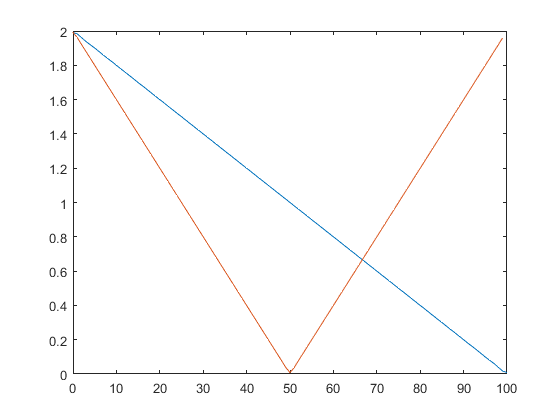

figure()
plot(k,magX); hold on
plot(n1,magY); hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

function [Xk] =dft(xn,N)
n= [0:1:N-1];
k=[0:1:N-1];
WN= exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^nk;
Xk=xn*WNnk;
end

function[xn]=idft(Xk,N)
n=[0:1:N-1];
k=[0:1:N-1];
WN=exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^(-nk);
xn=(Xk*WNnk)/N;
end

function[Xk]=dfs(xn,N)
n=[0:1:N-1];
k=[0:1:N-1];
WN=exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^nk;
Xk=xn*WNnk;
end